# ETOPO地形高程数据绘图

360百科及MATHWORK官网均表示，ETOPO地形数据有五种规格， ETOPO1的效果最好，NGDC 将 ETOPO2 和 ETOPO5 模型列为已弃用但仍可用。那么我们这期先讲如何使用MATLAB进行ETOPO数据绘图：

首先读取ETOPO数据MATLAB有两种函数都可以做到，一种是老版本函数etopo，另一种则是readgeoraster，一方面因为本人粉丝中用老版本的不在少数。另一方面readgeoraster推出较晚并不完善，理论上flt、hdr、bin等多种，格式数据都能读取。但实际试用时发现并不识别这几种类型数据，可以使用的只有`tif、dt1、grd`等几种数据，且允许过程中占用内存较大，因此在这只讲解etopo函数读取数据并绘图。etopo函数对于不同规格ETOPO地形数据数据支持情况如下：

ETOPO1c (cell)

- `etopo1_ice_c.flt`

- `etopo1_bed_c.flt`

- `etopo1_ice_c_f4.flt`

- `etopo1_bed_c_f4.flt`

- `etopo1_ice_c_i2.bin`

- `etopo1_bed_c_i2.bin`

ETOPO2V2c (cell)

- `ETOPO2V2c_i2_MSB.bin`

- `ETOPO2V2c_i2_LSB.bin`

- `ETOPO2V2c_f4_MSB.flt`

- `ETOPO2V2c_f4_LSB.flt`

- `ETOPO2V2c.hdf`

ETOPO2 (2001)

- `ETOPO2.dos.bin`

- `ETOPO2.raw.bin`

ETOPO5 (binary)

- `ETOPO5.DOS`

- `ETOPO5.DAT`

ETOPO5 (ASCII)

- `etopo5.northern.bat`

- `etopo5.southern.bat`

`我们要用的的是`ETOPO1c数据，因此我实际去官网下载了如下数据：

- `etopo1_ice_c_f4.flt 889MB`

- `etopo1_bed_c_f4.flt 889MB`

- `etopo1_ice_c_i2.bin 444MB`

- `etopo1_bed_c_i2.bin 444MB`

`数据集都不小哈，总体都两个多G了，要是想下载更多格式数据可以去这里（第一个连接是数据下载位置，第二个是官网位置）：`

[https://www.ngdc.noaa.gov/mgg/global/relief/ETOPO1/data/](https://www.ngdc.noaa.gov/mgg/global/relief/ETOPO1/data/)

[https://www.ngdc.noaa.gov/mgg/global/global.html](https://www.ngdc.noaa.gov/mgg/global/global.html)

### ETOPO1基岩基础绘制

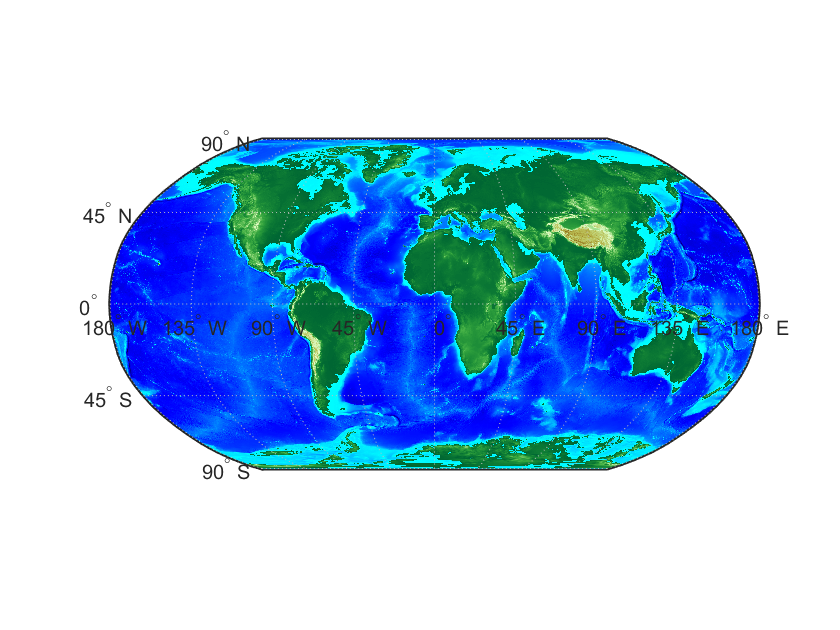

samplefactor=8;
[Z,refvec]=etopo('etopo1_bed_c_f4.flt', samplefactor);

worldmap('World')
geoshow(Z,refvec,'DisplayType','texturemap');

demcmap(Z,256)

### 某地区ETOPO1基岩绘制

#### `中国附近`

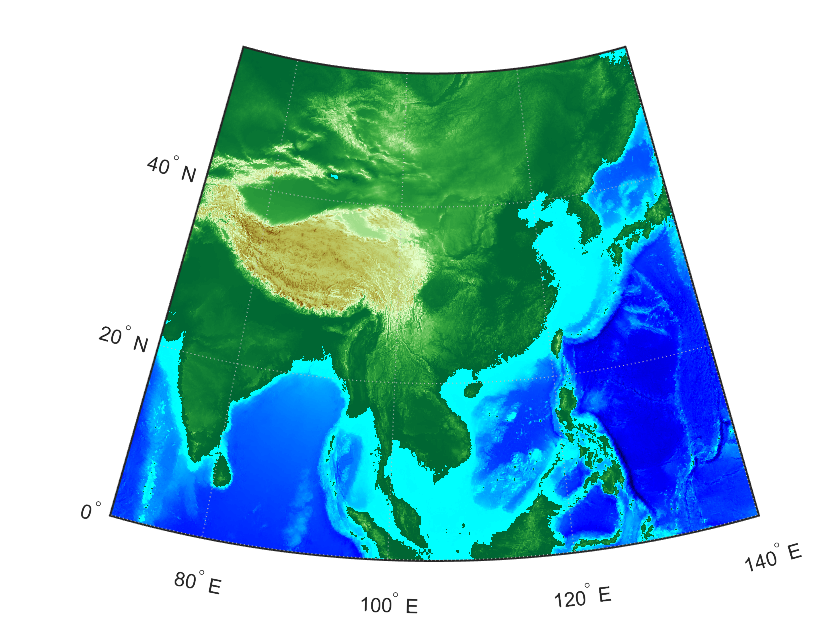

samplefactor=8;
[Z,refvec]=etopo('etopo1_bed_c_f4.flt', samplefactor);

worldmap('China')
geoshow(Z,refvec,'DisplayType','texturemap');

demcmap(Z,256)

#### `南极洲附近`

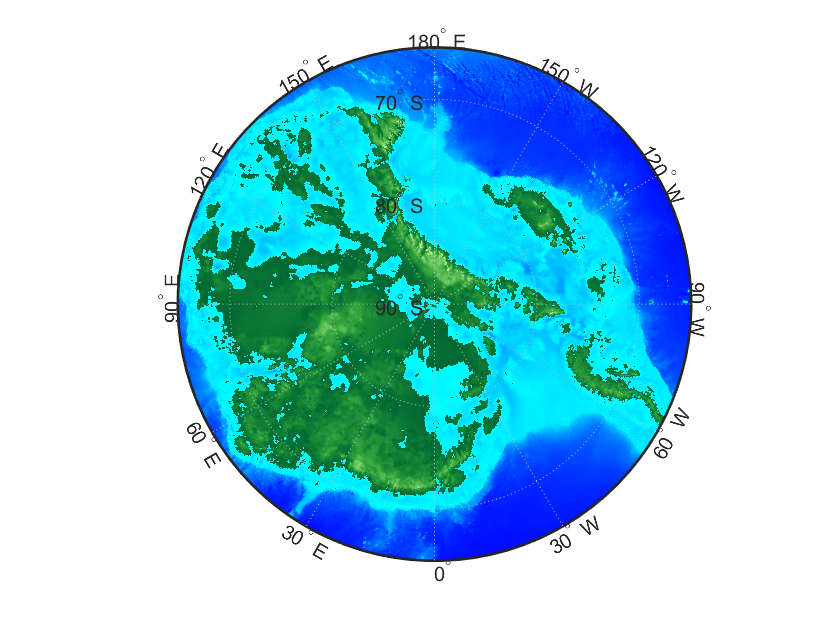

samplefactor=8;
[Z,refvec]=etopo('etopo1_bed_c_f4.flt', samplefactor);

worldmap('Antarctica')
geoshow(Z,refvec,'DisplayType','texturemap');

demcmap(Z,256)

#### `太平洋附近`

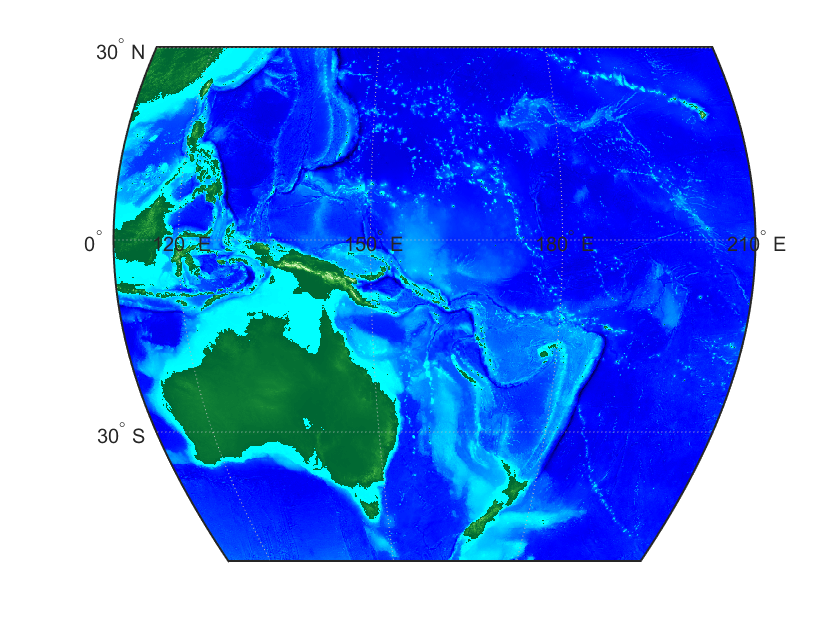

samplefactor=8;
[Z,refvec]=etopo('etopo1_bed_c_f4.flt', samplefactor);

worldmap('Pacific')
geoshow(Z,refvec,'DisplayType','texturemap');

demcmap(Z,256)

### ETOPO1绘图精度

samplefactor的数值代表绘图精度，数值越小越精确，等于 1 或者不填时精确度最高包含10800 x 21600个数据点。精度越高运行越慢，反之数值越大精度越低运行越快：

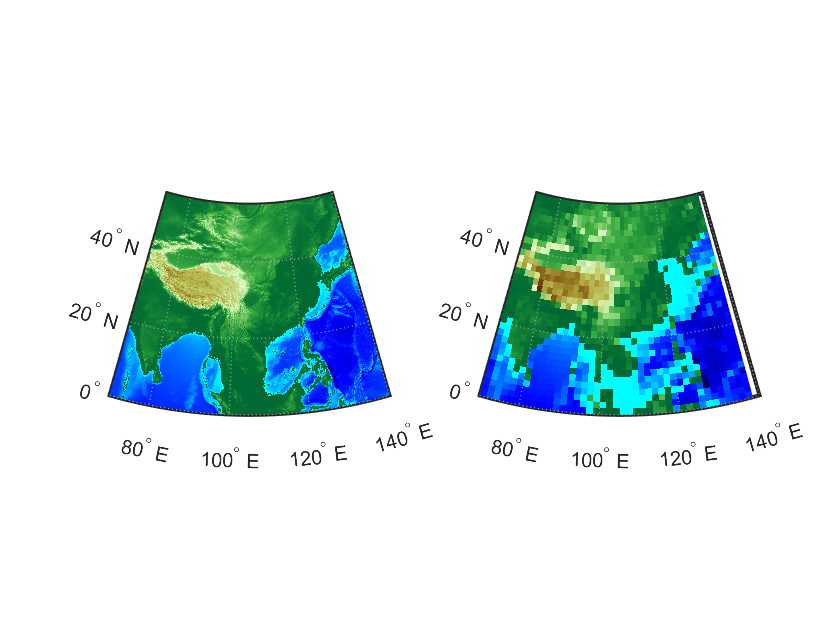

subplot(1,2,1)
samplefactor=8;
[Z,refvec]=etopo('etopo1_bed_c_f4.flt', samplefactor);

worldmap('China')
geoshow(Z,refvec,'DisplayType','texturemap');

demcmap(Z,256)

subplot(1,2,2)
samplefactor=100;
[Z,refvec]=etopo('etopo1_bed_c_f4.flt', samplefactor);

worldmap('China')
geoshow(Z,refvec,'DisplayType','texturemap');

demcmap(Z,256)

### ETOPO1范围读取：针对etopo函数

要是想绘制很高精度，光读取数据再绘制出图就得读取很久，我们可以只读取一定范围的数据：

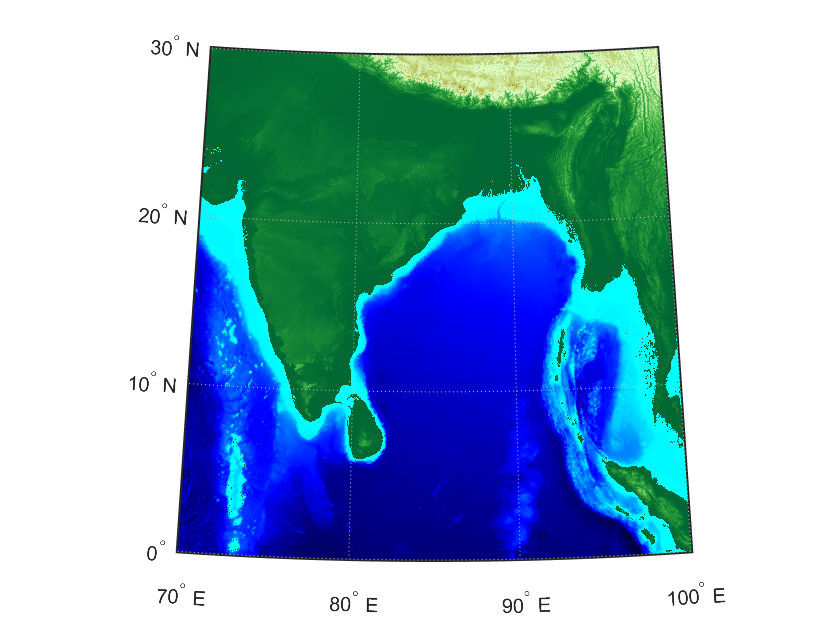

samplefactor=1;
[Z,refvec]=etopo('etopo1_bed_c_f4.flt', samplefactor,[0,30],[70,100]);

worldmap([0,30],[70,100])
geoshow(Z,refvec,'DisplayType','texturemap');

demcmap(Z,256)

### ETOPO1绘图配色

就和上一期一样，这里举几个例子：

**配色1**

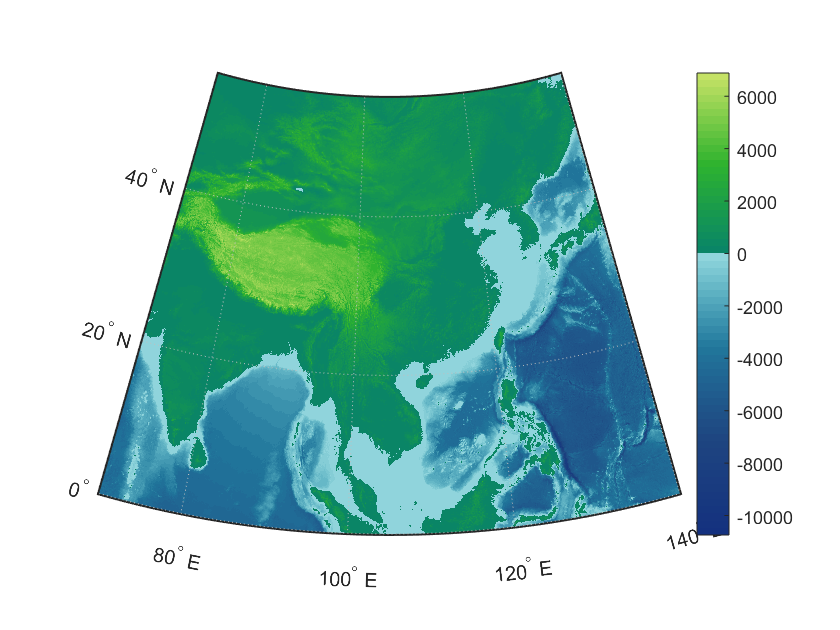

samplefactor=8;
[Z,refvec]=etopo('etopo1_bed_c_f4.flt', samplefactor);

worldmap('China')
geoshow(Z,refvec,'DisplayType','texturemap');

% 配色
cmapsea=[20,49,127;30,69,128;33,118,155;144,213,220]./255;
cmapland=[10,133,102;197,226,102]./255;
demcmap(Z,64,cmapsea,cmapland)
% 加颜色栏
colorbar

**配色2**

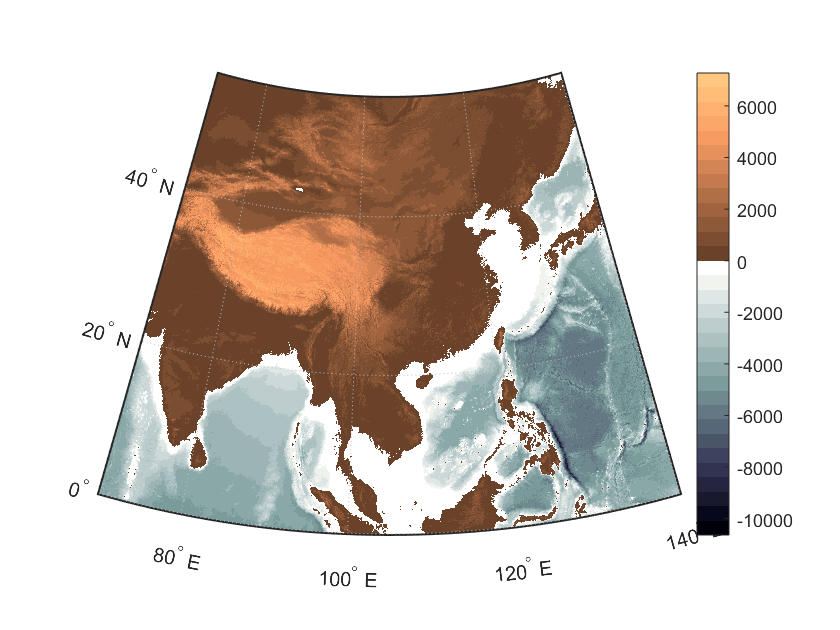

samplefactor=8;
[Z,refvec]=etopo('etopo1_bed_c_f4.flt', samplefactor);

worldmap('China')
geoshow(Z,refvec,'DisplayType','texturemap');

cmapcopper=copper(10);
demcmap(Z,32,bone(10),cmapcopper(4:end,:))
% 加颜色栏
colorbar

### ETOPO1冰盖基础绘制

就和陆地绘制一样，这里做个对比绘制个南极洲

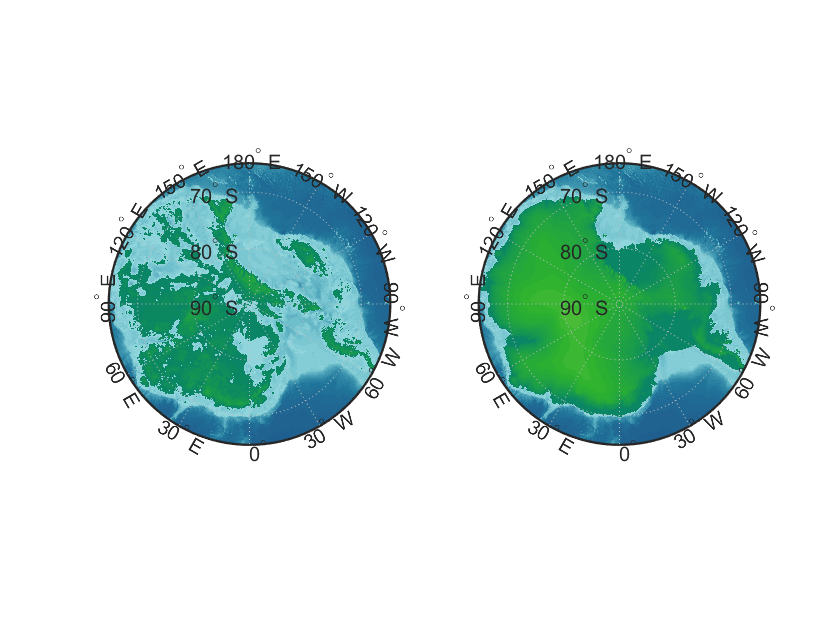

% 绘制基岩
subplot(1,2,1)
samplefactor=8;
[Z,refvec]=etopo('etopo1_bed_c_f4.flt', samplefactor);

worldmap('Antarctica')
geoshow(Z,refvec,'DisplayType','texturemap');

cmapsea=[20,49,127;30,69,128;33,118,155;144,213,220]./255;
cmapland=[10,133,102;197,226,102]./255;
demcmap(Z,64,cmapsea,cmapland)

% 绘制冰盖
subplot(1,2,2)
samplefactor=8;
[Z,refvec]=etopo('etopo1_ice_c_f4.flt', samplefactor);

worldmap('Antarctica')
geoshow(Z,refvec,'DisplayType','texturemap');

cmapsea=[20,49,127;30,69,128;33,118,155;144,213,220]./255;
cmapland=[10,133,102;197,226,102]./255;
demcmap(Z,64,cmapsea,cmapland)